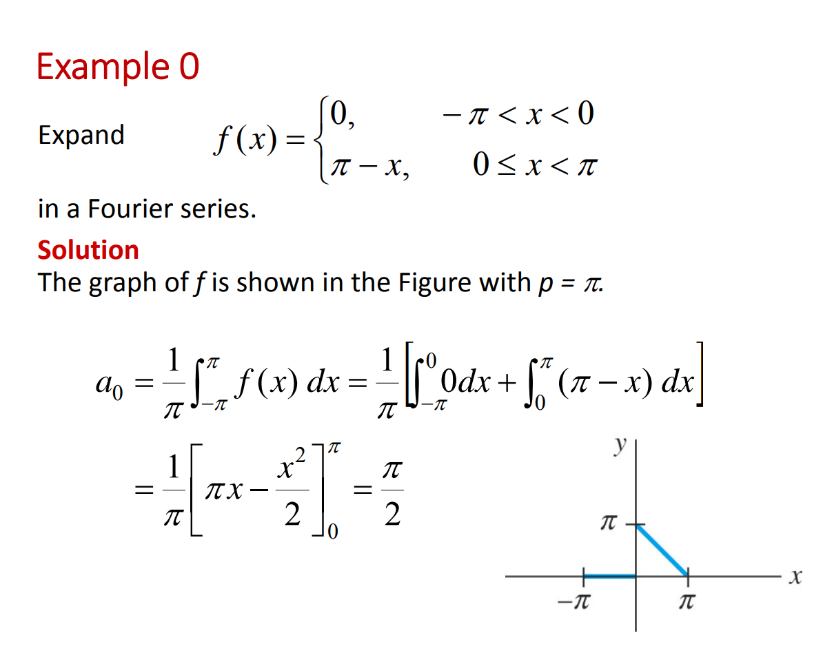

clear
clc
syms x n
b1 = [-pi,0]; b2 = [0,pi];
f1 = 0; f2 = pi-x;
a0 = eval((1/pi)*(int(f1,x,b1)+int(f2,x,b2)))

a0 = 1.5708

assume(n,"integer")
an = simplify((1/pi)*(int(f1*cos(n*x),x,b1)+int(f2*cos(n*x),x,b2)))

$$an = \frac{5734161139222659\,{\left(-1\right)}^{n+1}\,{\left({\left(-1\right)}^{n}-1\right)}^{2}}{36028797018963968\,n^{2}}$$

eval(an)

$$ans = \frac{5734161139222659\,{\left(-1\right)}^{n+1}\,{\left({\left(-1\right)}^{n}-1\right)}^{2}}{36028797018963968\,n^{2}}$$

bn = simplify((1/pi)*(int(f1*sin(n*x),x,b1)+int(f2*sin(n*x),x,b2)))

$$bn = \frac{5734161139222659\,\pi }{18014398509481984\,n}$$

f0 = an*cos(n*x)+bn*sin(n*x);
harm = 3;

**Plot graphs**

for i = 1:harm
    fx = a0/2+symsum(f0,n,[1 i]);
    subplot(harm+1,1,i)
    fplot(fx,[-3*pi 3*pi])
    title('Harmonic')
    xlabel('time')
end
hold on

**Plot Input**

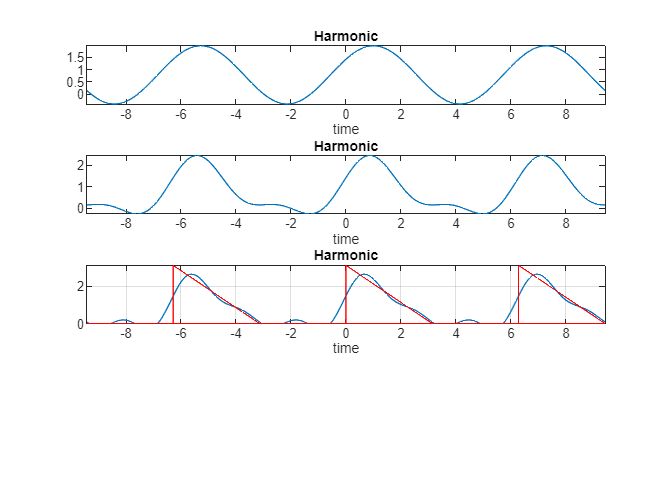

t = -3*pi:1/1000:3*pi;
xf1 = pi*tripuls(t+3*pi/2,pi,-1);
xf2 = pi*tripuls(t-pi/2,pi,-1);
xf3 = pi*tripuls(t-5*pi/2,pi,-1);
plot(t,xf1,'r',t,xf2,'r',t,xf3,'r')
ylim([0 pi])
grid on

**Spectrum plot**

i = 1:harm;
mg = eval(sqrt(subs(an,n,i).^2+subs(bn,n,i).^2));
mag = [a0 mg]

mag =     1.5708    1.1854    0.5000    0.3408


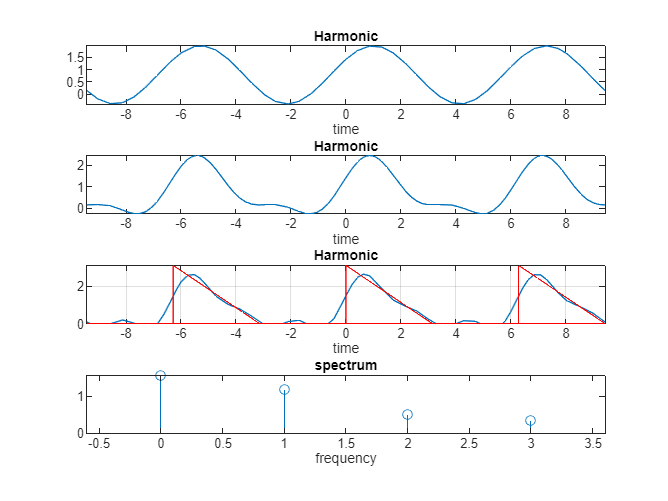

subplot(harm+1,1,harm+1)
stem([0 i],mag)
 title('spectrum')
 xlabel('frequency')